# Nota legata de istoricul metodei lui Newton

Polinomul $x^3-2x-5$a fost utilizat de Walis pentru a prezenta prima data metoda lui Newton Academiei Franceze. El are o radacina reala, intre $x=2$ si $x=3$ si o pereche de radacini complexe conjugate.

## Rezolvare simbolica

syms x
z=solve(x.^3-2*x-5==0, x, 'MaxDegree',3)

$$z = \begin{array}{l} \left(\begin{array}{c} \frac{2}{3\,\sigma_{2}}+\sigma_{2}\\ -\frac{1}{3\,\sigma_{2}}-\frac{\sigma_{2}}{2}-\sigma_{1}\\ -\frac{1}{3\,\sigma_{2}}-\frac{\sigma_{2}}{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\left(\frac{2}{3\,\sigma_{2}}-\sigma_{2}\right)\,\mathrm{i}}{2}\\ \sigma_{2}={\left(\frac{\sqrt{108}\,\sqrt{643}}{108}+\frac{5}{2}\right)}^{1/3} \end{array}$$

double(z)

ans =   2.094551481542327 + 0.000000000000000i
 -1.047275740771163 + 1.135939889088928i
 -1.047275740771163 - 1.135939889088928i


Reprezentare grafica

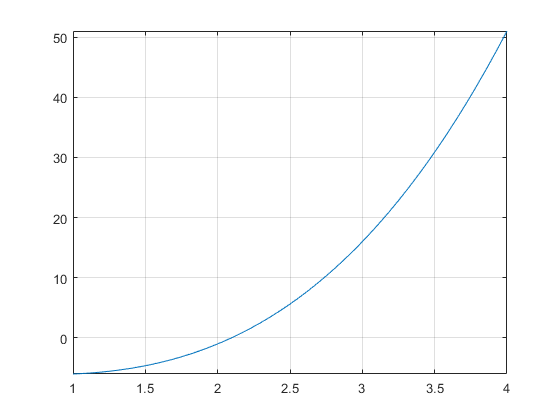

fplot(x.^3-2*x-5,[1,4]);
grid on

clear

## Rezolvare numerica 

Radacina reala

f = @(x) x^3-2*x-5;
fd = @(x) 3*x^2-2;
x0 = 3;
[z,ni] = Newtons(f,fd,x0,1e-6,0,20)

z =    2.094551481542347


ni =      5


Radacina complexa

x0=1i;
[z2,ni2] = Newtons(f,fd,x0,1e-6,0,20)

z2 =  -1.047275740771163 + 1.135939889088928i


ni2 =      8


x0=-1i;
[z3,ni3] = Newtons(f,fd,x0,1e-6,0,20)

z3 =  -1.047275740771163 - 1.135939889088928i


ni3 =      8


Codul pentru metoda lui Newton:

function [z,ni]=Newtons(f,fd,x0,ea,er,Nmax)
%NEWTONS - metoda lui Newton pentru ecuatii in R
%Intrare
%f - functia
%fd - derivata
%x0 - valoarea de pornire
%ea,er - eroarea absoluta, respectiv relativa
%Nmax - numar maxim de iteratii
%Iesire
%z - aproximatia solutiei
%ni - numar de iteratii

if nargin<6, Nmax=50; end
if nargin<5, er=0; end
if nargin<4, ea=1e-3; end
xv=x0;
for k=1:Nmax
    xc=xv-f(xv)/fd(xv);
    if abs(xc-xv)<ea+er*abs(xc) %succes
        z=xc;
        ni=k;
        return
    end
    xv=xc; %pregatesc iteratia urmatoare
end
%esec
error('s-a depasit numarul maxim de iteratii')
end